load("data_ca4.mat");
%measurement time
fs = 128

fs = 128

m_time=(heart_beats(106379)-heart_beats(1))./fs

m_time = 8.0966e+04

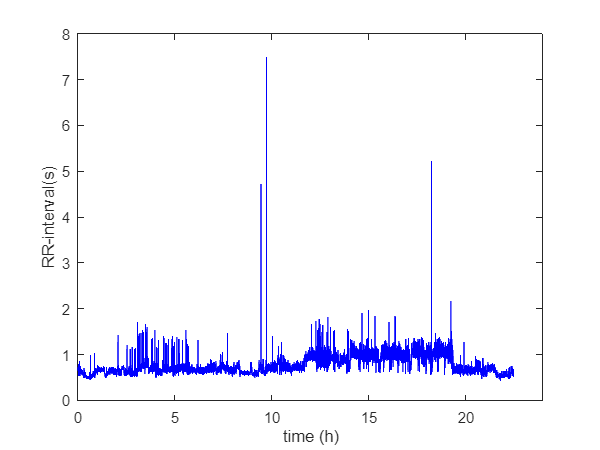

%let's calculate the distances between beats
distances=[];
for i=1:length(heart_beats)-1
    d = heart_beats(i+1)-heart_beats(i);
    distances=[distances,d];
end
%change to seconds
dist_t=distances./fs;

hours=linspace(0,m_time/60^2,length(dist_t));
plot(hours,dist_t,'b-')
xlim([0 24])
xlabel('time (h)')
ylabel("RR-interval(s)")

%SDNN
sdnn=std(dist_t)

sdnn = 0.1718


%SDANN
period = 394; % 5 minute period, about 394 peaks

% Let's calculate means
means = [];
for j = 1:ceil(length(dist_t)/period)
    start = (j-1)*period + 1;
    ending = min(j*period, length(dist_t));
    avg = mean(dist_t(start:ending));
    means = [means, avg];
end

%calculate SDANN
sdann = std(means)

sdann = 0.1556


%RMSSD
% squared differences
d_dist=diff(dist_t).^2;

%calculate rmssd
rmssd=sqrt(mean(d_dist))

rmssd = 0.0580


%pNN50

NN50=sum(abs(diff(dist_t))>0.05);

pNN50=(NN50/(length(dist_t)-1))*100

pNN50 = 8.8177

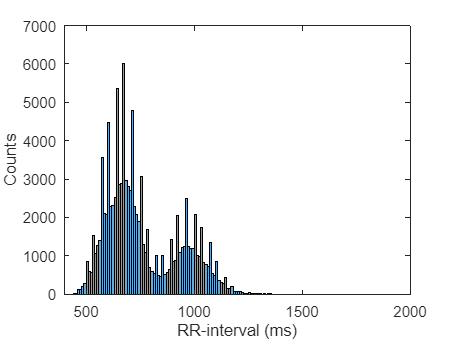


figure
histogram(dist_t*1000)
xlim([400 2000])
xlabel('RR-interval (ms)')
ylabel('Counts')


%Triangular HRV index

triangular_hrv=length(dist_t)/6021

triangular_hrv = 17.6678

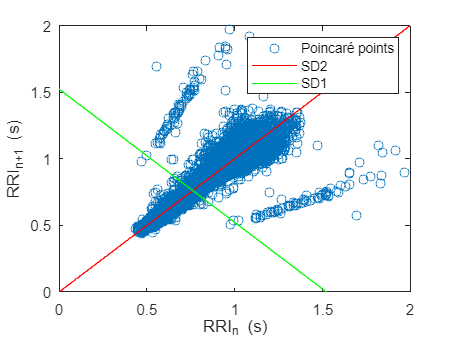


%Poincare
pc_1=[];
pc_2=[];
for k = 1:length(dist_t)-1
    pc_k=dist_t(k);
    pc_k2=dist_t(k+1);
    pc_1=[pc_1,pc_k];
    pc_2=[pc_2,pc_k2];
end
plot(pc_1,pc_2,'o')
xlim([0 2])
ylim([0 2])
xlabel('RRI_n (s)')
ylabel('RRI_n+1 (s)')
hold on
x=0:0.1:2;
plot(x,x,'r-')
plot(x,-x+2.*mean(dist_t),'g-')
legend('Poincaré points','SD2','SD1')